%% Independent work 10 - Monte Carlo Method (Part 2)

clear all
clc

disp("Independent work 10 - Monte Carlo Method (Part 2).");

Independent work 10 - Monte Carlo Method (Part 2).


disp("Question 01.");

Question 01.



%% Define functions and parameters
f_a = @(x) sqrt((3-2*x)./(2*x-7));
f_b = @(x) (x.^2 + 5*x + 6).*cos(2*x);

% Integration limits
a1 = 2; b1 = 3;      % limits for integral a
a2 = -2; b2 = -1;    % limits for integral b

%% Print significant variables
fprintf('Significant Variables:\n');

Significant Variables:


fprintf('Integration limits for function a: [%.1f, %.1f]\n', a1, b1);

Integration limits for function a: [2.0, 3.0]


fprintf('Integration limits for function b: [%.1f, %.1f]\n', a2, b2);

Integration limits for function b: [-2.0, -1.0]



% Sample sizes
N_values = [10, 100, 1000, 10000];

%% Method I Implementation (sum of f(xi)/N)
results_a_m1 = zeros(1, length(N_values))

results_a_m1 =      0     0     0     0


results_b_m1 = zeros(1, length(N_values))

results_b_m1 =      0     0     0     0



for i = 1:length(N_values)
    N = N_values(i);
    
    % For function a
    x_rand = a1 + (b1-a1)*rand(N, 1);
    y_rand = f_a(x_rand);
    valid_values = y_rand(~isnan(y_rand));  % Remove NaN values
    sum_valid = sum(valid_values);
    results_a_m1(i) = (b1-a1) * (sum_valid / length(valid_values));
    
    % For function b
    x_rand = a2 + (b2-a2)*rand(N, 1);
    y_rand = f_b(x_rand);
    valid_values = y_rand(~isnan(y_rand));  % Remove NaN values
    sum_valid = sum(valid_values);
    results_b_m1(i) = (b2-a2) * (sum_valid / length(valid_values));
end

%% Method II Implementation (Nc/N * (b-a))

results_a_m2 = zeros(1, length(N_values))

results_a_m2 =      0     0     0     0


results_b_m2 = zeros(1, length(N_values))

results_b_m2 =      0     0     0     0



% Calculate f_max values once
x_test_a = linspace(a1, b1, 10000);
x_test_b = linspace(a2, b2, 10000);
f_max_a = max(f_a(x_test_a));
f_max_b = max(f_b(x_test_b));

%% Print significant variables
fprintf('Significant Variables:\n');

Significant Variables:


fprintf('Function a f_max: %.4f\n', f_max_a);

Function a f_max: 1.7321


fprintf('Function b f_max: %.4f\n\n', f_max_b);

Function b f_max: -0.0000




for i = 1:length(N_values)
    N = N_values(i);
    
    % For function a
    x_rand = a1 + (b1-a1)*rand(1, N);
    y_rand = f_max_a * rand(1, N);
    y_curve = f_a(x_rand);
    Nc = sum(y_rand <= y_curve);
    results_a_m2(i) = (Nc / N) * (b1 - a1);
    
    % For function b
    x_rand = a2 + (b2-a2)*rand(1, N);
    y_rand = f_max_b * rand(1, N);
    y_curve = f_b(x_rand);
    Nc = sum(y_rand <= y_curve);
    results_b_m2(i) = (Nc / N) * (b2 - a2);
end

fprintf('Results:\n');

Results:


fprintf('Function a:\n');

Function a:


fprintf('N\t\tMethod I\t\tMethod II\n');

N		Method I		Method II


for i = 1:length(N_values)
    fprintf('%d\t\t%.6f\t\t%.6f\n', N_values(i), results_a_m1(i), results_a_m2(i));
end

10		1.047222		0.600000
100		1.063366		0.580000
1000		1.070612		0.625000
10000		1.051795		0.600700



fprintf('\nFunction b:\n');


Function b:


fprintf('N\t\tMethod I\t\tMethod II\n');

N		Method I		Method II


for i = 1:length(N_values)
    fprintf('%d\t\t%.6f\t\t%.6f\n', N_values(i), results_b_m1(i), results_b_m2(i));
end

10		-0.825638		0.000000
100		-0.643736		0.000000
1000		-0.663045		0.000000
10000		-0.637909		0.000000


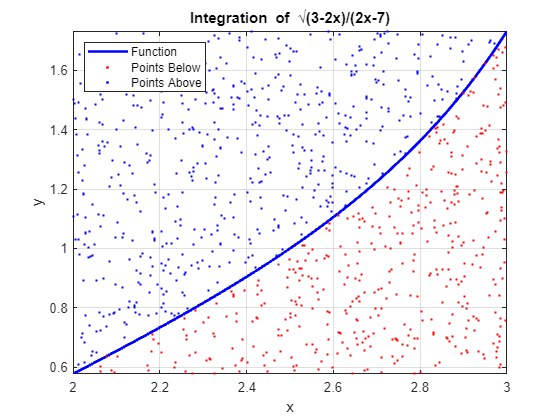


%% Plotting
% Create visualization for N=1000 demonstration
N_vis = 1000;

% Function a visualization
figure(1);
[ymin_a, ymax_a] = find_y_range(f_a, a1, b1);
x_rand = a1 + (b1-a1)*rand(N_vis, 1);
y_rand = ymin_a + (ymax_a-ymin_a)*rand(N_vis, 1);
y_curve = f_a(x_rand);
points_below = y_rand <= y_curve;

% Plot function
fplot(f_a, [a1 b1], 'b', 'LineWidth', 2);
hold on;
scatter(x_rand(points_below), y_rand(points_below), 20, 'r', '.');
scatter(x_rand(~points_below), y_rand(~points_below), 20, 'b', '.');
xlabel('x'); ylabel('y');
grid on;
title('Integration of \surd{(3-2x)/(2x-7)}');
legend('Function', 'Points Below', 'Points Above', 'Location', 'NorthWest');
hold off;

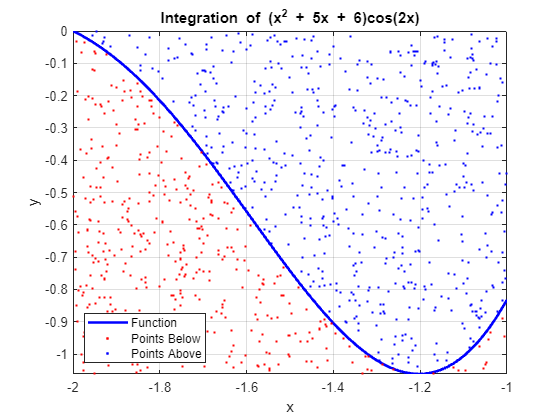


% Function b visualization
figure(2);
[ymin_b, ymax_b] = find_y_range(f_b, a2, b2);
x_rand = a2 + (b2-a2)*rand(N_vis, 1);
y_rand = ymin_b + (ymax_b-ymin_b)*rand(N_vis, 1);
y_curve = f_b(x_rand);
points_below = y_rand <= y_curve;

% Plot function
fplot(f_b, [a2 b2], 'b', 'LineWidth', 2);
hold on;
scatter(x_rand(points_below), y_rand(points_below), 20, 'r', '.');
scatter(x_rand(~points_below), y_rand(~points_below), 20, 'b', '.');
xlabel('x'); ylabel('y');
grid on;
title('Integration of (x^2 + 5x + 6)cos(2x)');
legend('Function', 'Points Below', 'Points Above', 'Location', 'SouthWest');
hold off;

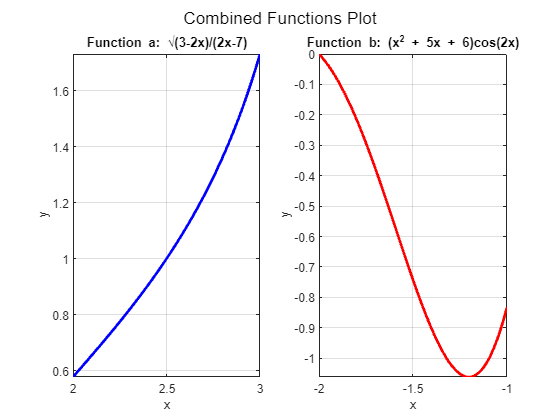


% Combined plot
figure(3);
subplot(1,2,1);
fplot(f_a, [a1 b1], 'b', 'LineWidth', 2);
title('Function a: \surd{(3-2x)/(2x-7)}');
xlabel('x'); ylabel('y');
grid on;

subplot(1,2,2);
fplot(f_b, [a2 b2], 'r', 'LineWidth', 2);
title('Function b: (x^2 + 5x + 6)cos(2x)');
xlabel('x'); ylabel('y');
grid on;

sgtitle('Combined Functions Plot');


% Function to find y range


function [ymin, ymax] = find_y_range(f, a, b)
    x = linspace(a, b, 1000);
    y = f(x);
    ymin = min(y);
    ymax = max(y);
end
